# Applying the Lawler-Fujita algorithm and distortion subtraction by Gao et al. (2017) to real STM images

Update for Real_3.mlx with the additional features that DNaS_6.mlx has on it's update from DNaS_5.mlx.

## 1    Importing an image

[~, lattice] = loadsxm('FeSeS_14p_Topo_015.sxm', 1);
% lattice = double(im2gray(imread('zhao.png')));

name = "FeSe_{0.86}S_{0.14}";

units = "nm";
conversion_factor = 5.6236/0.369; % [pixel/units]

lambda = 0.2; % [atom^-1]
confidence_level = 0.99;
cf = conversion_factor;

#### Image specifications

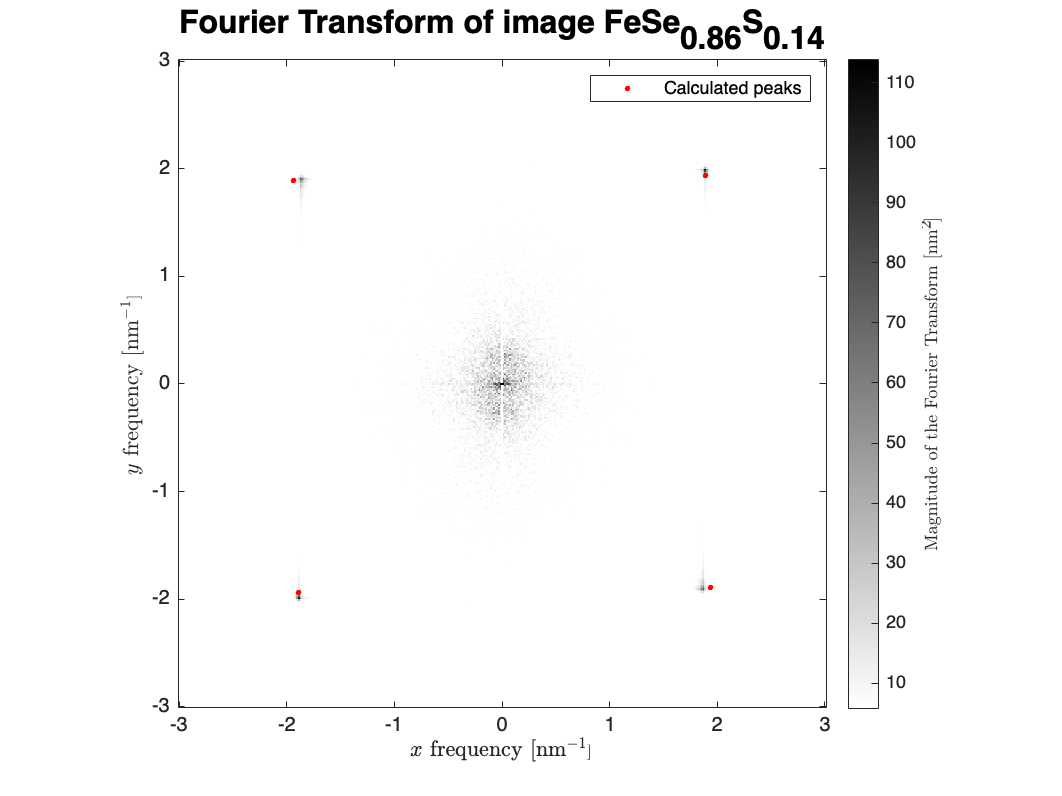

myFFT() estimates that the 2D lattice is perfect square.


[image_height, image_length] = size(lattice);

% lattice = reshape(normalize(lattice(:)),image_height,image_length);
% lattice = (lattice-mean(lattice,2))./std(lattice,1,2);
% normalize per row. Adapted from Kirsty's topo042401.m

lattice = lattice-mean(lattice,2);

% NOTICE!
px_per_nm = 11.7489/0.369;
lattice = (lattice-min(lattice,[],"all"))*(10^9)*px_per_nm;
% because the data from the STM is in meters —Kirsty

[lattice_fft, Qbragg] = myFFT(lattice,name,cscale='linear', ...
    units=units,cf=cf,cunits=units,ccf=cf);

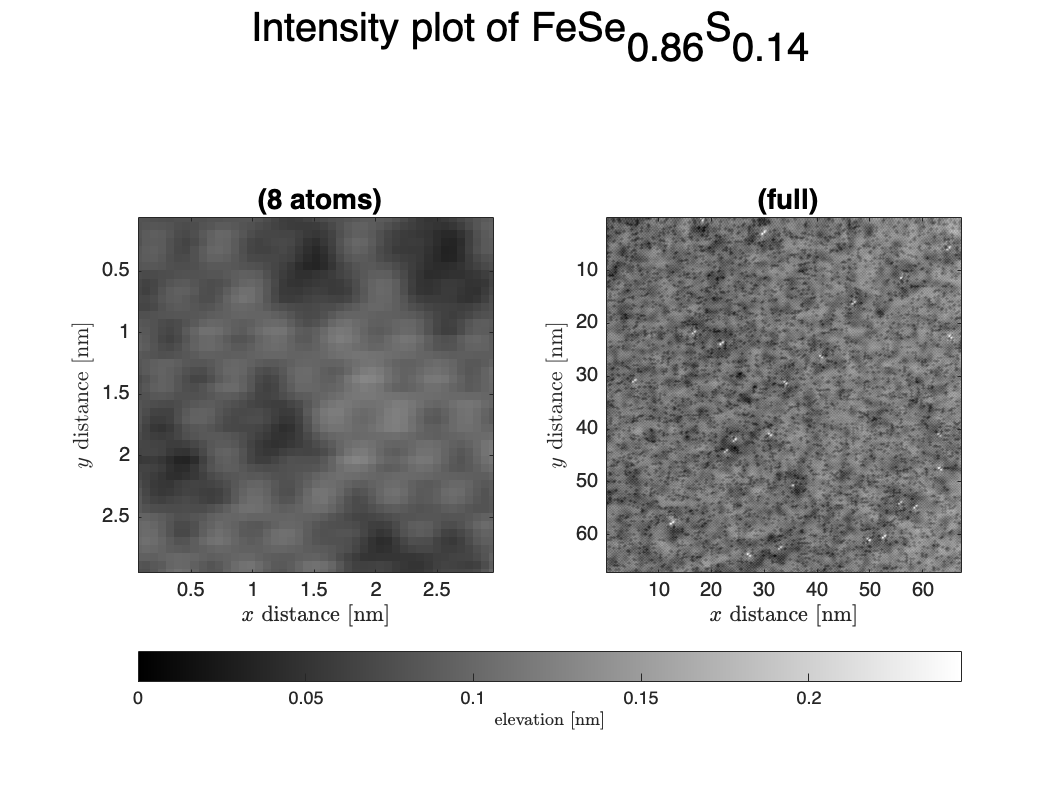


crystal_structures = ["square", "hexagonal"];
crystal = crystal_structures(size(Qbragg,2)-1);

lcs = 1./sqrt((Qbragg(1,:)/image_length).^2+(Qbragg(2,:)/image_height).^2); % [pixel]
lc = mean(lcs);

Qbragg = Qbragg * 2*pi ./ (vecnorm(Qbragg)*lc);

if crystal=="hexagonal"
    lc = lc*sqrt(3)/2;
end

comboPlot(lattice,name,lc, units=units, cf=cf, cunits=units, ccf=cf);

Pre-processing the inputs, converting units. You might probably would't want to edit these.

disp("image height = " + image_height/cf + " ["+units+"], " + ...
    image_height + " [px]")

image height = 67.1911 [nm], 1024 [px]


disp("image length = " + image_length/cf + " ["+units+"], " + ...
    image_length + " [px]")

image length = 67.1911 [nm], 1024 [px]


disp("lattice constant = " + lc/cf + " ["+units+"], " + ...
    lc + " [px]");

lattice constant = 0.369 [nm], 5.6236 [px]


disp("crystal structure: " + crystal);

crystal structure: square


disp("Lambda used = " + lambda + " [lc^-1]");

Lambda used = 0.2 [lc^-1]



for ctr = 1:size(Qbragg,2)
    disp("Q_" + ctr + " = (" + Qbragg(1,ctr)/(2*pi)*cf + ", " + ...
        Qbragg(2,ctr)/(2*pi)*cf + ") ["+units+"^-1]");
end

Q_1 = (1.8976, 1.9348) [nm^-1]
Q_2 = (-1.9348, 1.8976) [nm^-1]



lambda = lambda/lc;

zscore = zscorer(confidence_level);

## 2    Calculating total distortion

Using the Lawler-Fujita algorithm, the total distortion as the sum of the imaging distortion and the physical strain, $\vec{u}_{calc}=\vec{d}+\vec{s}$, is calculated. The effects of noise and the magnitude and type of tolerable distortion could be studied using the previous and the following code.

BranchCuts: No residues, length(rowres)=0; sum(abs(residue_charge))=0; sum(abs(residue_charge_masked))=0


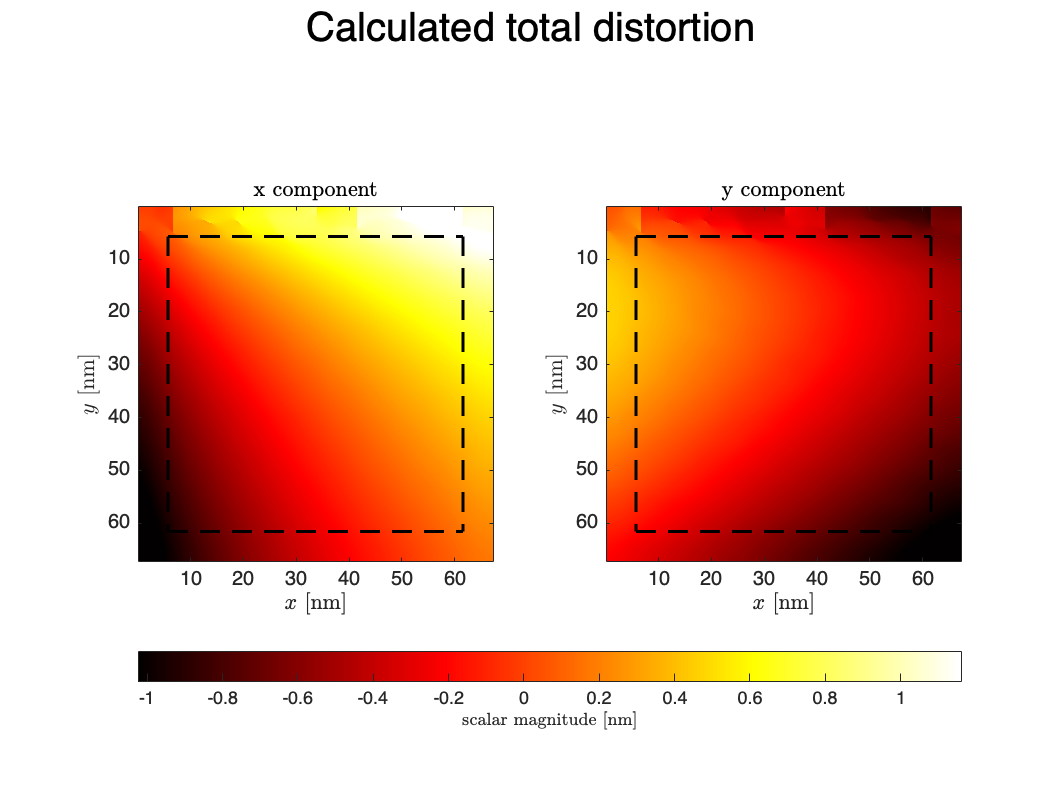

ucalc = myConv(lattice,Qbragg,lambda,zscore,units=units,cf=cf,cunits=units,ccf=cf);

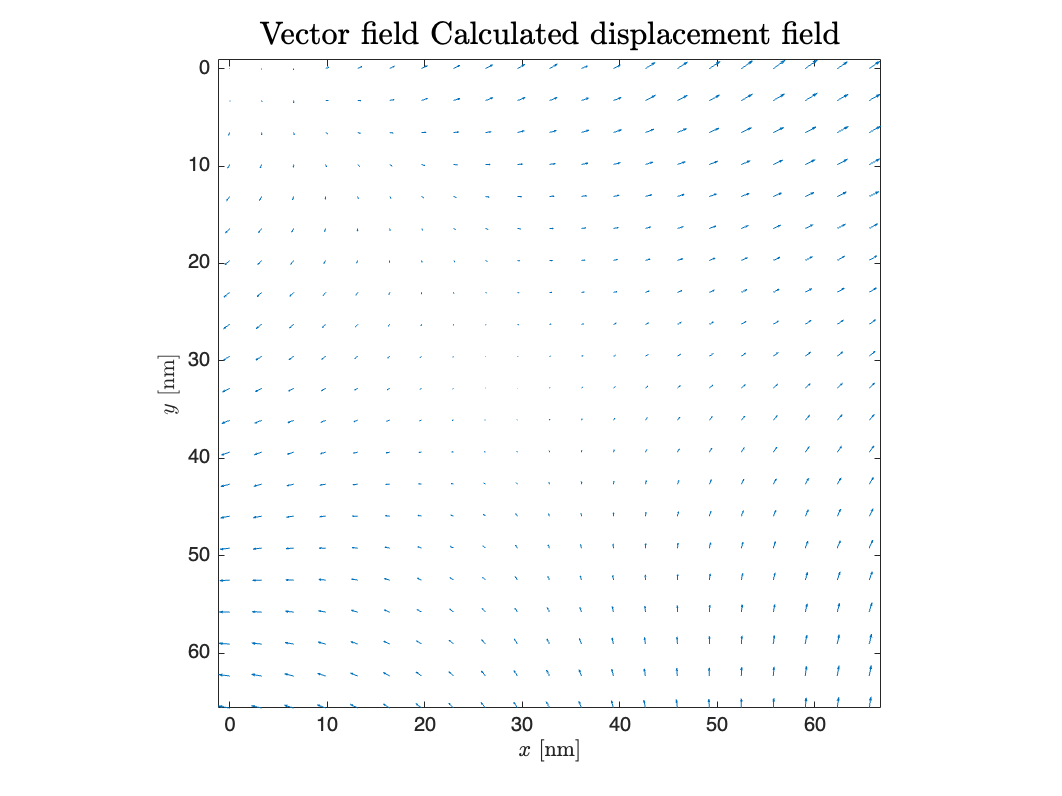


figure;
uPlot(ucalc,"Calculated displacement field",units=units,cf=cf,cunits=units,ccf=cf);


if image_length-2*ceil(zscore/lambda)<=0 && image_height-2*ceil(zscore/lambda)<=0
    error("ERROR! No pixels without padded zeros remain.");
else
    npixel = (image_length-2*ceil(zscore/lambda))*(image_height-2*ceil(zscore/lambda));
    % the number of pixels averaged
    disp("Number of pixels averaged: " + npixel + " (" + ...
        npixel/(image_length*image_height)*100 + "%)");
end

Number of pixels averaged: 725904 (69.2276%)


## 3    Undistorting the image

We undistort the image using my own undistort() function that in turn uses the imwarpConverse() function that I also built.

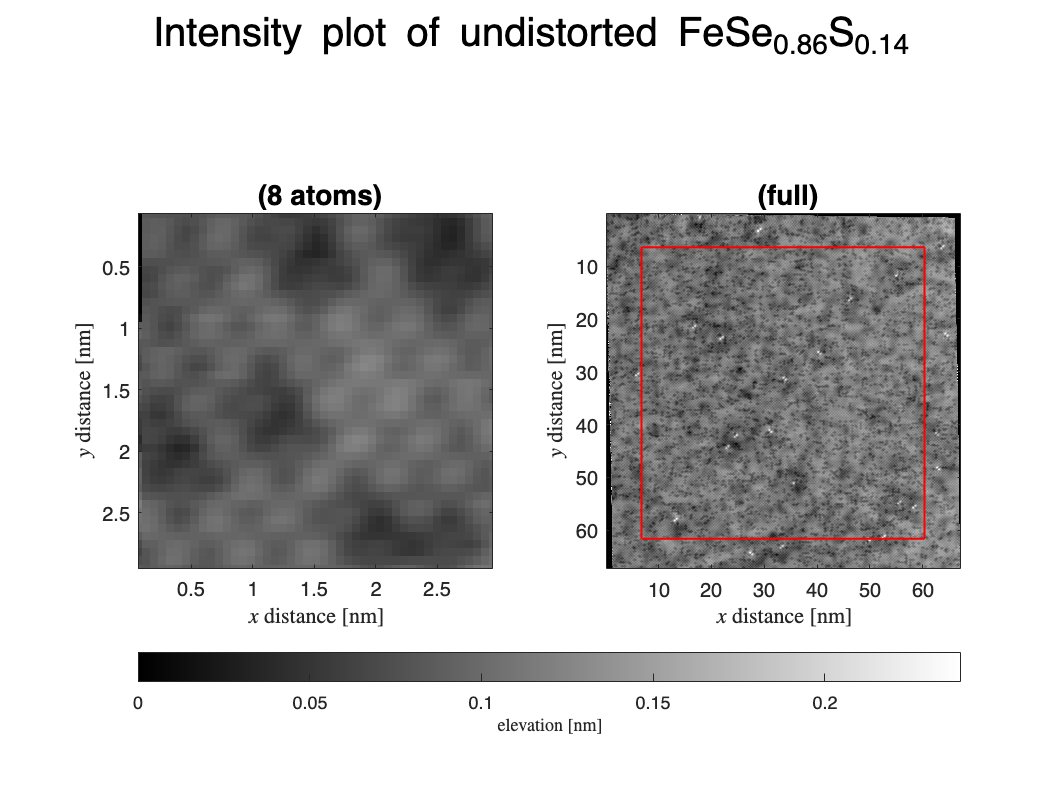

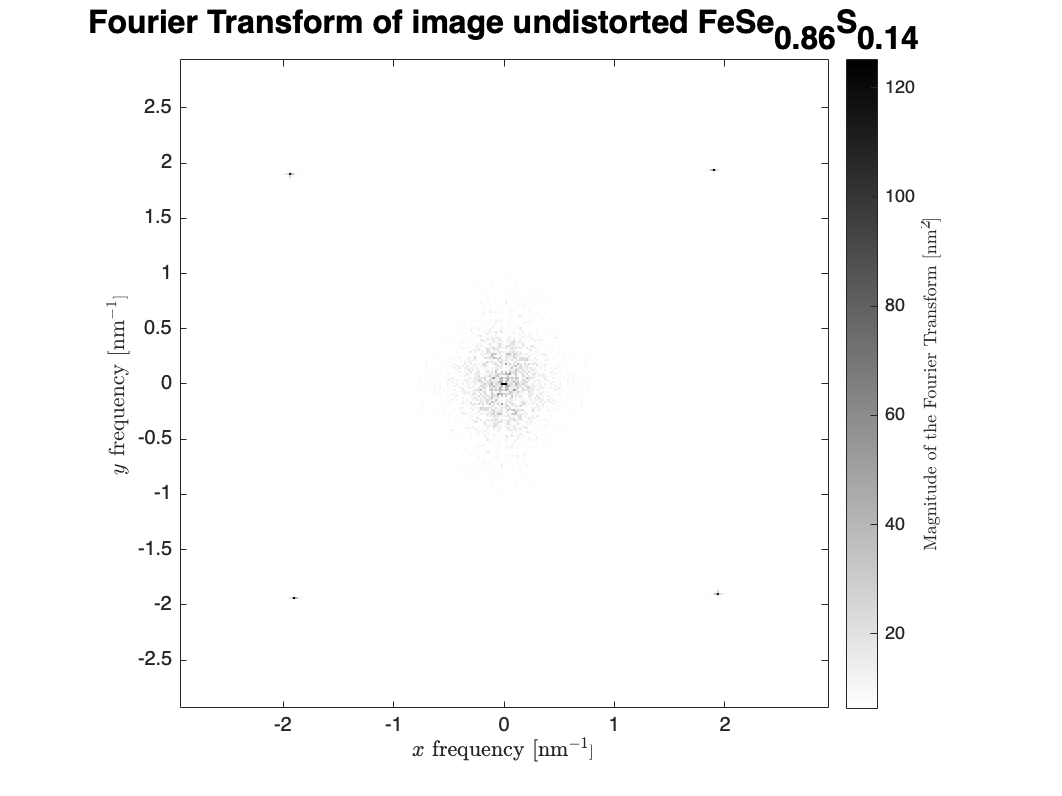

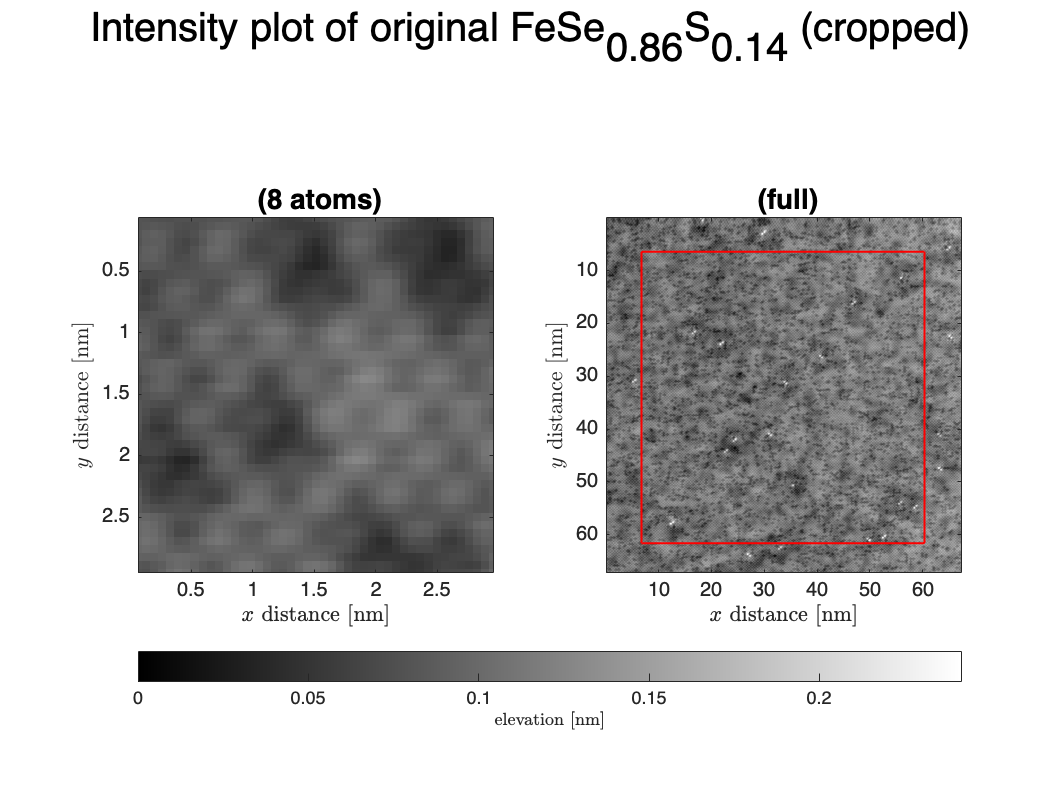

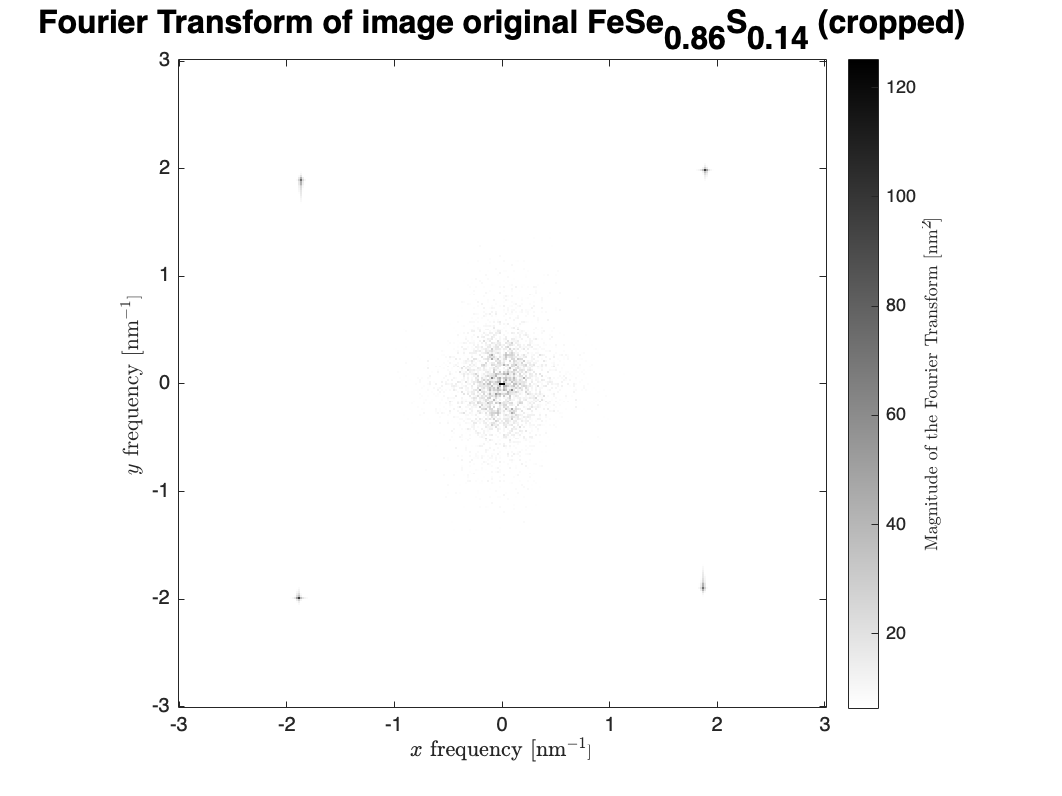

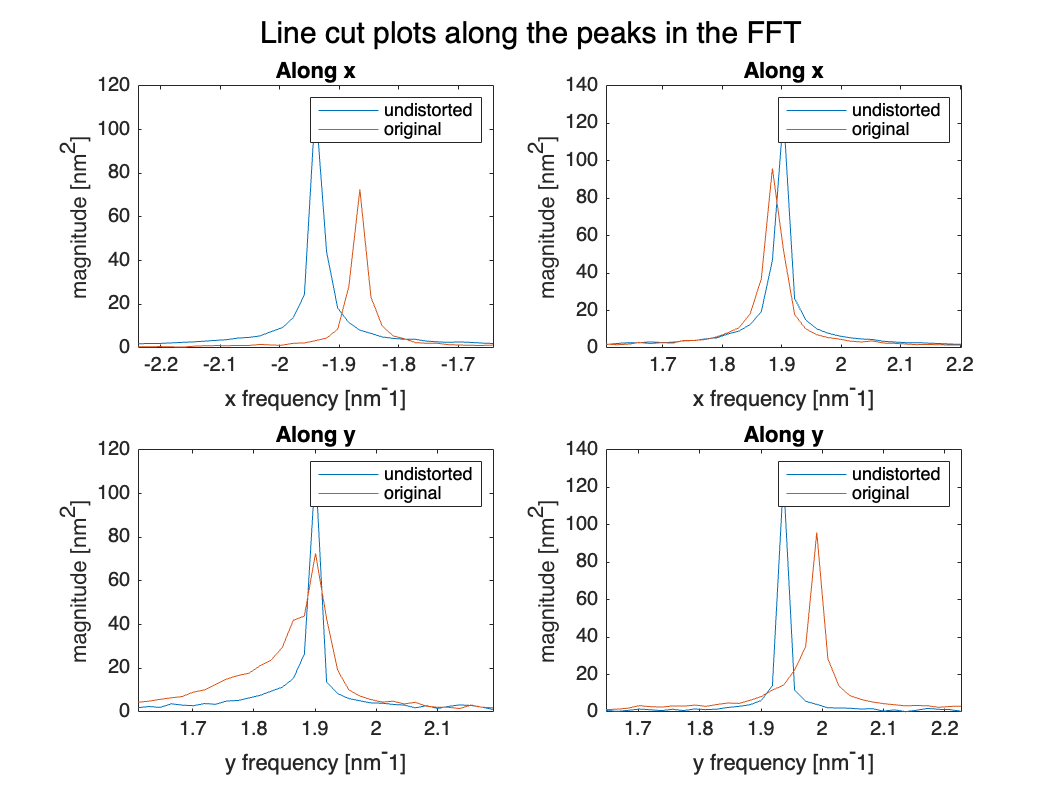

ulattice = undistort(lattice,-ucalc,lc,lambda,zscore, cscale='linear', ...
    name_undistorted="undistorted " + name, name_cropped="original " + name + " (cropped)", ...
    cryst_struct=crystal, linecuts=true, units=units,cf=cf,cunits=units,ccf=cf);

## 4    Calculating physical strain

From the equation given above, the physical strain can be obtained by subtracting the smooth, third-digree polynomial imaging distortion from the total distortion.

rot_angle = 0;
[fitresultx, gofx,outputx] = createFit(ucalc(:,:,1), lambda,zscore, rot_angle=rot_angle);

Doing polynomial fit using MATLAB's poly33.


[fitresulty, gofy,outputy] = createFit(ucalc(:,:,2), lambda,zscore, rot_angle=rot_angle);

Doing polynomial fit using MATLAB's poly33.


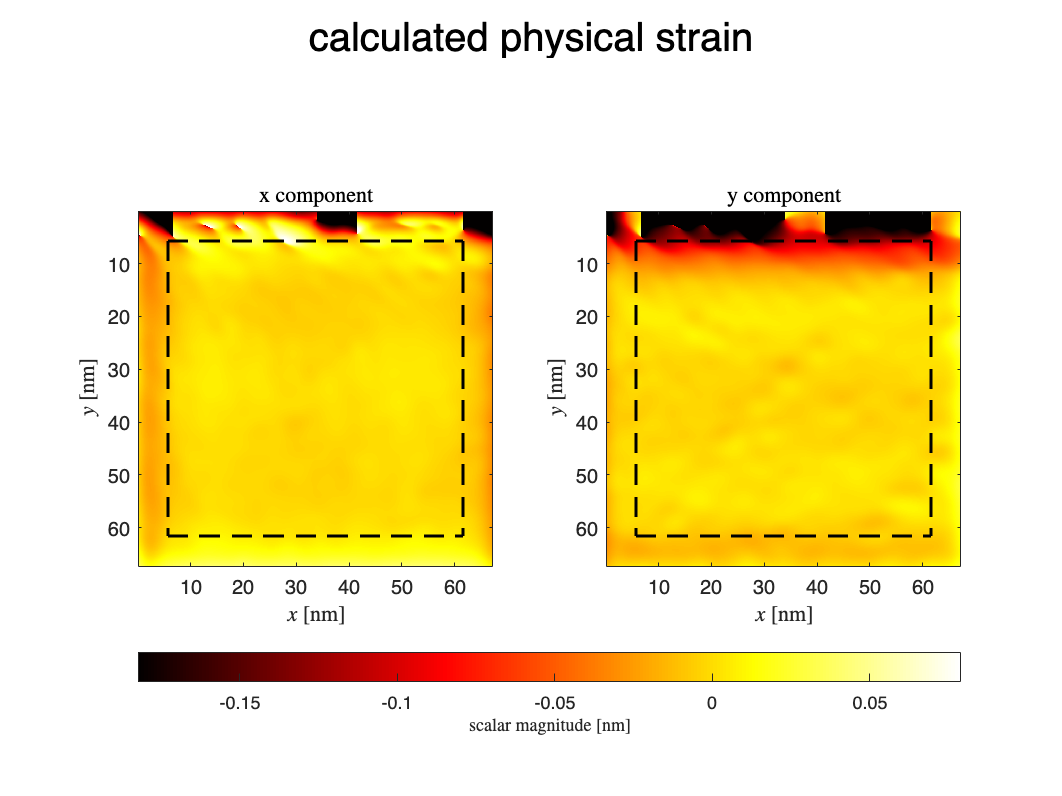


% to adjust for the [0,1] range of coordinates x,y,t
% and to avoid 'bad equation condition' warning
[xi,yi] = meshgrid(0:1/image_length:(image_length-1)/image_length ...
    ,0:1/image_height:(image_height-1)/image_height);
[xi,yi] = rotateMeshgrid(xi,yi,rot_angle);

strain = zeros(size(ucalc));
strain(:,:,1) = ucalc(:,:,1)-fitresultx(xi,yi);
strain(:,:,2) = ucalc(:,:,2)-fitresulty(xi,yi);

convPlot(strain(:,:,1),"calculated physical strain",strain(:,:,2),lambda,zscore, ...
    units=units, cf=cf, cunits=units,ccf=cf);

The strain and it's first order partial derivatives are calculated and plotted. Biaxial and approximate uniaxial strain maps are also generated from the previous calculations.

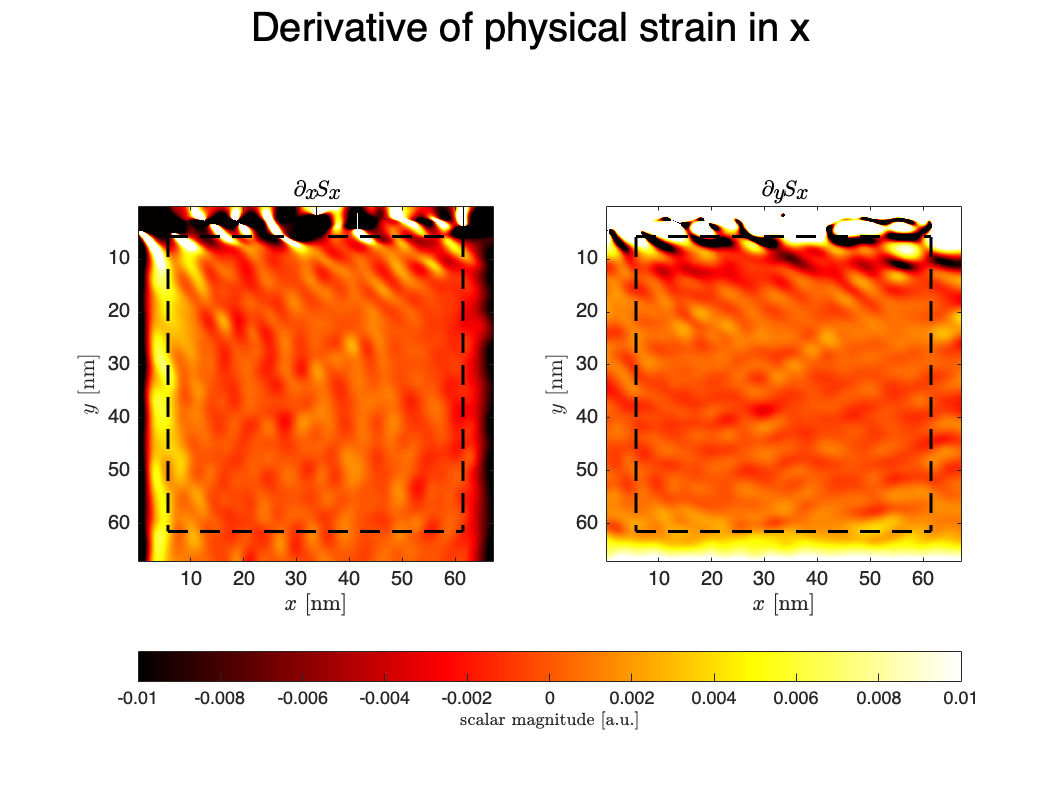

Sxdx = diff(strain(1:end-1,:,1),1,2);
Sxdy = diff(strain(:,1:end-1,1));
Sydx = diff(strain(1:end-1,:,2),1,2);
Sydy = diff(strain(:,1:end-1,2));

climits_strain = [-1 1]*1e-2;
convPlot(Sxdx,["Derivative of physical strain in x", ...
    "$\partial_xS_x$","$\partial_yS_x$"],Sxdy,lambda,zscore, ...
    units=units,cf=cf,cunits="a.u.",ccf=1, climits=climits_strain);

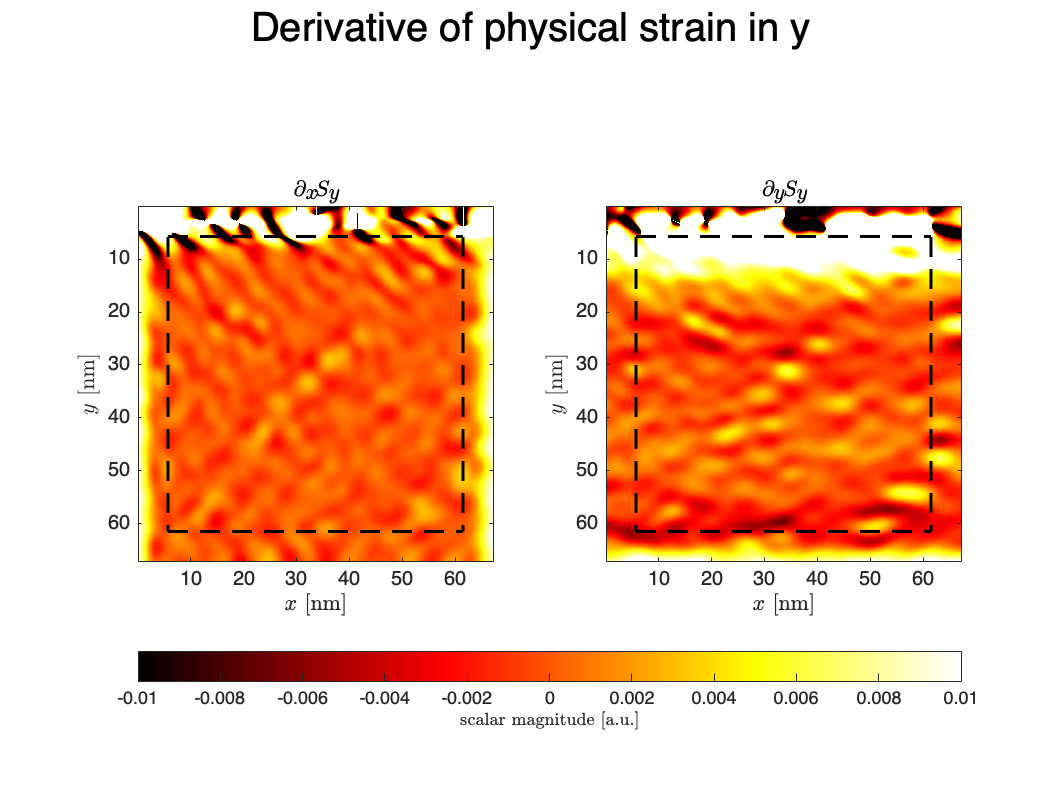

convPlot(Sydx,["Derivative of physical strain in y", ...
    "$\partial_xS_y$","$\partial_yS_y$"],Sydy,lambda,zscore, ...
    units=units,cf=cf,cunits="a.u.",ccf=1, climits=climits_strain);

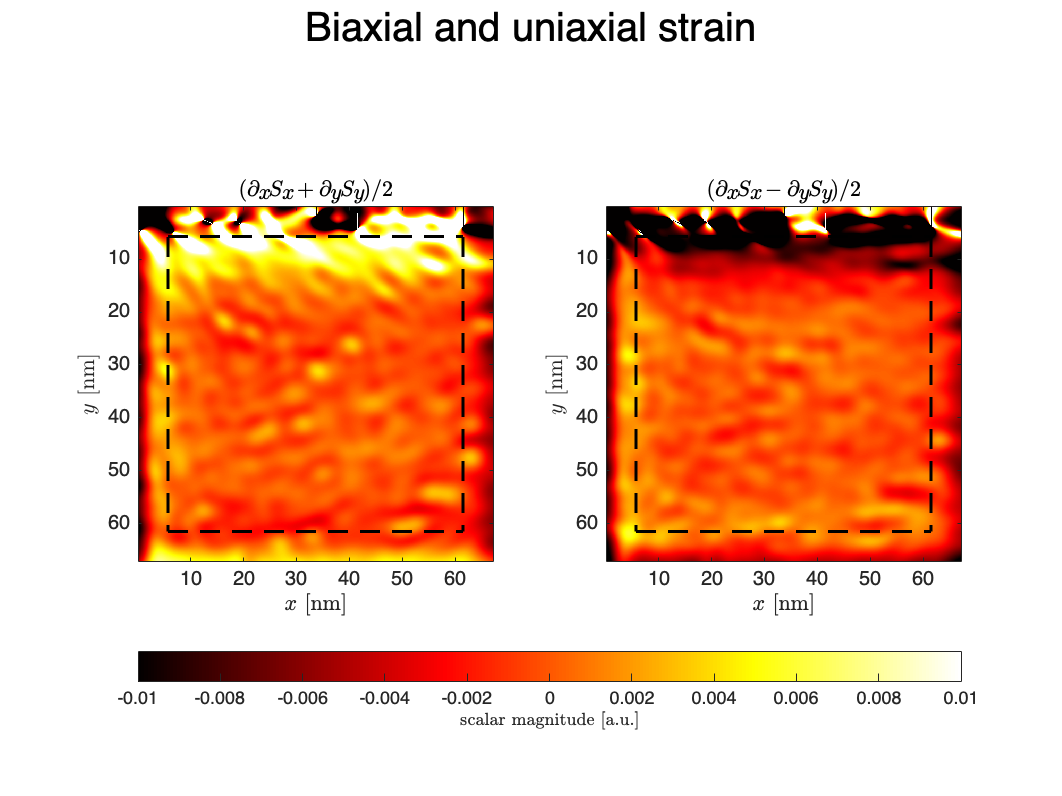

convPlot((Sxdx+Sydy)/2,["Biaxial and uniaxial strain", ...
    "$(\partial_xS_x+\partial_yS_y)/2$", "$(\partial_xS_x-\partial_yS_y)/2$"], ...
    (Sxdx-Sydy)/2,lambda,zscore, units=units,cf=cf,cunits="a.u.",ccf=1, ...
    climits=climits_strain);


[bmean, bstd] = uCompare(Sxdx,Sydy,lambda,zscore);
[umean, ustd] = uCompare(Sxdx,-Sydy,lambda,zscore);
disp("biaxial mean = " + bmean);

biaxial mean = 0.0010855


disp("biaxial std = " + bstd);

biaxial std = 0.0040709


disp("uniaxial mean = " + umean);

uniaxial mean = -0.00097628


disp("uniaxial std = " + ustd);

uniaxial std = 0.0033581
